Welcome to the controller script for the data processing and figure generation of the BRFS manuscript as submitted to iScience.

By running this script you should be able to process our event-locked data, use Gramm to plot continuous data, and then format datastructures of subsequent stastical analysis in JASP.

clear
close all

saveData = false;

global  FORMDATDIR OUTDIR STIMDIR

STIMDIR = 'D:\brfs_STIM_220811';
FORMDATDIR   = 'C:\Users\Brock Carlson\Box\BRFS to iScience\FormattedDataOutputs\';
OUTDIR   = 'C:\Users\Brock Carlson\Documents\MATLAB\PlotOutputs\';

try
    cd(FORMDATDIR)
    cd(OUTDIR)
catch errorOutput
    warning('Setup the data input and the plot output directories')
end

Now we must load in the data from Zenodo. This structure contains pre-processed data of units tuned to eye and orientation. 

The pre-processing code is contained within this repository. If you would like the raw data files to test it out for yourself please do not hesitate to contact us:

    brock.m.carlson@vanderbilt.edu

cd(FORMDATDIR)
dataFileName = 'carlsonEtAl_iScienceFigs_allTunedUnits';
load(strcat(FORMDATDIR,strcat(filesep,dataFileName,'.mat')))



Now we create images with Gramm.

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


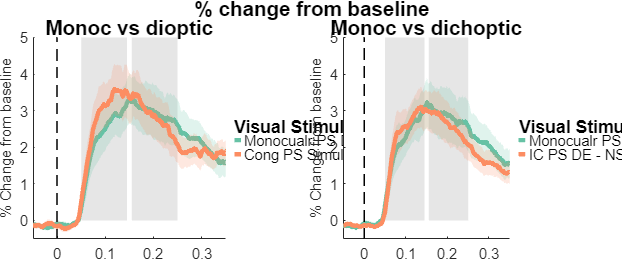

% IDX breakdown
numUnits = idxBreakdown(IDX,ERR);

%% Figure 2a and 2b
gramm_dCOS_line(IDX);

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


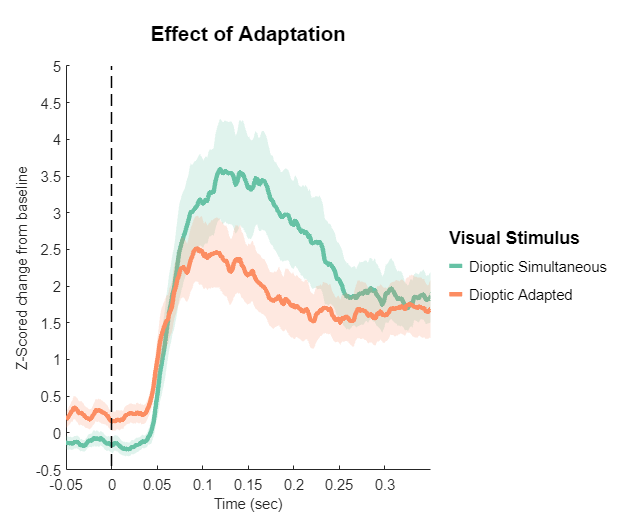


% Figure 2c
gramm_adaptation_line(IDX)

ans =   1×2 gramm array with properties:

    legend_axe_handle
    title_axe_handle
    facet_axes_handles
    results


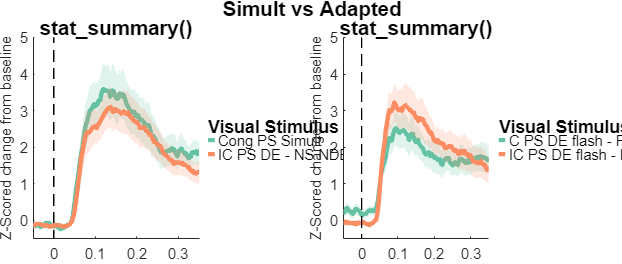


% Figure 3
gramm_2x2_line(IDX)

ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: []


ans =   gramm with properties:

     legend_axe_handle: []
      title_axe_handle: []
    facet_axes_handles: []
               results: [1×1 struct]


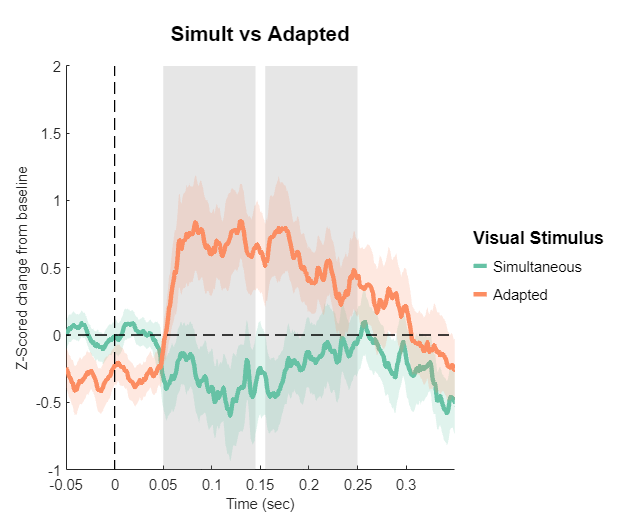

gramm_2x2_subline(IDX)

ans =   gramm with properties:

     legend_axe_handle: [1×1 Axes]
      title_axe_handle: [1×1 Axes]
    facet_axes_handles: [1×1 Axes]
               results: [1×1 struct]


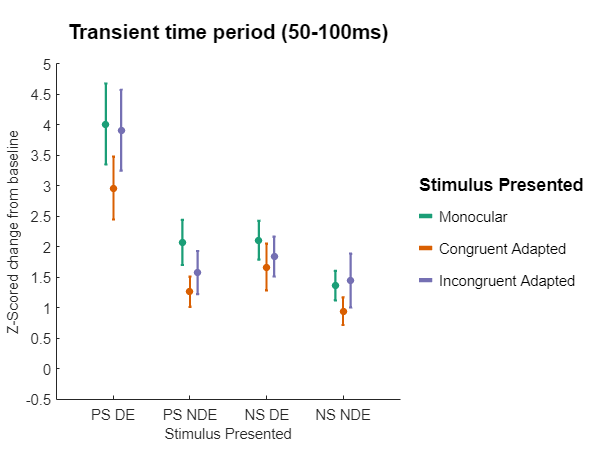


% Figure 4
gramm_adaptationEffect(IDX)

## JASP

Next we format the IDX output into a .csv that JASP can accept

Because we are running a repeated measures t-tests and a repeated measures ANOVA, the results must be formateed (A x B) where A is each unit and B are the various conditions possible. The contents of each cell is the average response (within a given time-window) for a given unit to all presentations of that column's condition. Note that there will be missing conditions for each unit because not all conditions were shown on any individual day. Furthermore, while the condition shown to the subjects were selected for the majority of unit preferences on any given day, there are frequently a few units tuned to the ipsilateral eye and orthagonal orientation. Because preferences are established from the unit's perspective, some units will not have the prefered stimulus shown to the dominant eye. JASP does a good job of tracking and correcting for missing values. You can select to ignore missing values listwise or conditionwise. Typically, it is best practice to ignore missing values listwise to keep the degrees of freedomn identical between contrasts.

%% JASP conversion
% JASP requires each unit to be in a row vector with each column as the
% different conditions.
% Currently each row of IDX.allV1 is for its own unit (that's good).
% IDX.allV1.RESP_avg contains a 24x1 cell, where each cell contains the
% average for all 4 time periods of the RESP vector. 
% We have 24 potential conditions
% The output required are 88 x 24 arrays.
% We need 1 array for the transient period and 1 array for the sustained.
% win_ms is [transient, sustained, whole time, baseline]

numberOfUnits = size(IDX.allV1,2);

for i = 1:numberOfUnits
    for j = 1:24
        outputForJASP_transient(i,j) = IDX.allV1(i).RESP_avg{j}(1);
        outputForJASP_sustained(i,j) = IDX.allV1(i).RESP_avg{j}(2);
    end
end

%% Writetable
% Now we need to export these values to .csv for JASP import. It would be
% great if I did not have to input 24 condition labels by hand

conditionLabels = IDX.allV1(1).condition;
conditionNames = conditionLabels.Properties.RowNames;
outputForJASP_transient_table = array2table(outputForJASP_transient);
outputForJASP_sustained_table = array2table(outputForJASP_sustained);

outputForJASP_transient_table.Properties.VariableNames = conditionNames;
outputForJASP_sustained_table.Properties.VariableNames = conditionNames;

cd(FORMDATDIR)
if saveData
    saveNameTrans = strcat('JASP_transient_',anaName,'.csv');
    saveNameSus     = strcat('JASP_sustained_',anaName,'.csv');
    writetable(outputForJASP_transient_table,saveNameTrans)
    writetable(outputForJASP_sustained_table,saveNameSus)
end